# Practica 2: Operaciones con Señales de Tiempo Discreto

1.    Una señal de tiempo discreto x(n) se define como: 


$$x(n) = \delta(n) + u(n+4) -2u(n)+u(n-5)$$


a) Utilice Matlab para generar y graficar $x(n)$

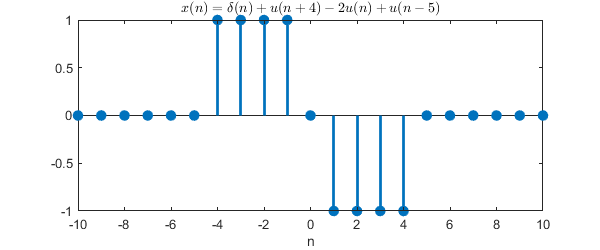

x1 = @(n) ( impulso(n) + escalon(n+4) - 2*escalon(n) + escalon(n-5) );
n = -10:10;
figure('Position',[500 400 600 250])
stem(n,x1(n),'filled','LineWidth',2)
title('$ x(n) = \delta(n) + u(n+4) -2u(n)+u(n-5) $','Interpreter','latex')
xlabel('n')

b) Utilice Matlab para generar y graficar $x(n-5)$

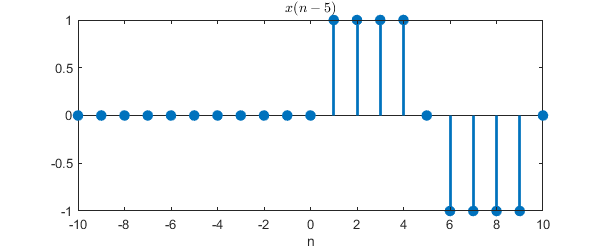

x1 = @(n) ( impulso(n) + escalon(n+4) - 2*escalon(n) + escalon(n-5) );
n = -10:10;
figure('Position',[500 400 600 250])
stem(n,x1(n-5),'filled','LineWidth',2)
title('$ x(n-5) $','Interpreter','latex')
xlabel('n')

c) Utilice Matlab para generar y graficar $x(n+5)$

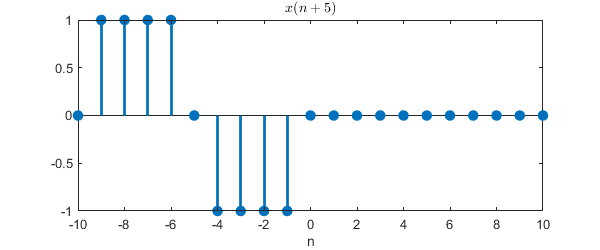

x1 = @(n) ( impulso(n) + escalon(n+4) - 2*escalon(n) + escalon(n-5) );
n = -10:10;
figure('Position',[500 400 600 250])
stem(n,x1(n+5),'filled','LineWidth',2)
title('$ x(n+5) $','Interpreter','latex')
xlabel('n')

d) Utilice Matlab para generar y graficar $x(-n)$

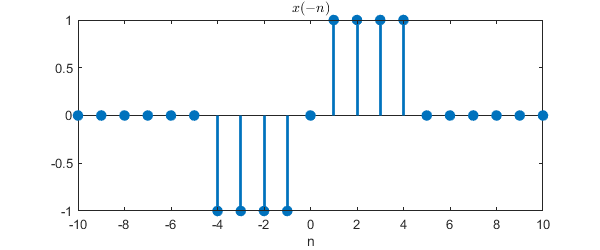

x1 = @(n) ( impulso(n) + escalon(n+4) - 2*escalon(n) + escalon(n-5) );
n = -10:10;
figure('Position',[500 400 600 250])
stem(n,x1(-n),'filled','LineWidth',2)
title('$ x(-n) $','Interpreter','latex')
xlabel('n')

e) Utilice Matlab para generar y graficar $x(-n+5)$

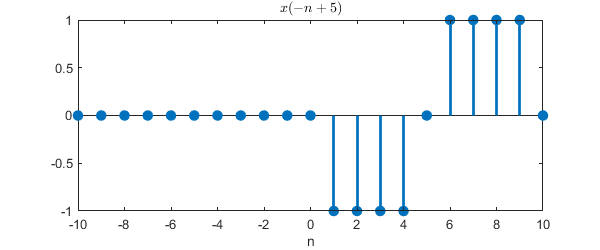

x1 = @(n) ( impulso(n) + escalon(n+4) - 2*escalon(n) + escalon(n-5) );
n = -10:10;
figure('Position',[500 400 600 250])
stem(n,x1(-n+5),'filled','LineWidth',2)
title('$ x(-n+5) $','Interpreter','latex')
xlabel('n')

f) Utilice Matlab para generar y graficar $x(-n-5)$

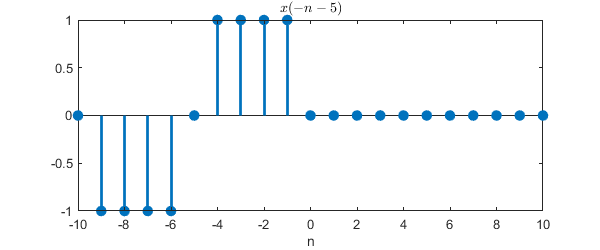

x1 = @(n) ( impulso(n) + escalon(n+4) - 2*escalon(n) + escalon(n-5) );
n = -10:10;
figure('Position',[500 400 600 250])
stem(n,x1(-n-5),'filled','LineWidth',2)
title('$ x(-n-5) $','Interpreter','latex')
xlabel('n')

2.    Una señal de tiempo discreto se define como:

 
$$x(n) = u(n+4)-u(n-5)$$


a) Utilice Matlab para generar y graficar la señal:


$$y_1(n) = \frac{1}{3}x(n+1)+ \frac{1}{3}x(n)+ \frac{1}{3}x(n-1)$$


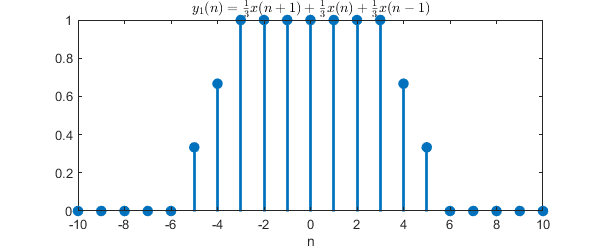

x2 = @(n) ( escalon(n+4)-escalon(n-5) );
y1 = @(n) ( (1/3)*( x2(n+1) + x2(n) + x2(n-1) ) );
n = -10:10;
figure('Position',[500 400 600 250])
stem(n,y1(n),'filled','LineWidth',2)
title('$ y_1(n) = \frac{1}{3}x(n+1)+ \frac{1}{3}x(n)+ \frac{1}{3}x(n-1) $','Interpreter','latex')
xlabel('n')

b) Utilice Matlab para generar y graficar la señal:


$$y_2(n) =(\frac{4}{5})^n x(n)$$


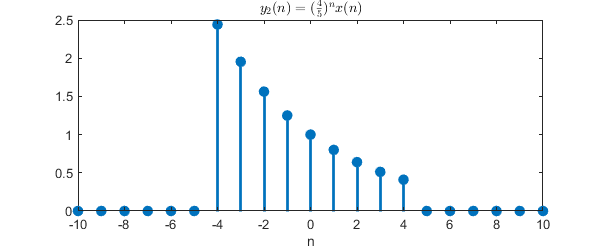

x2 = @(n) ( escalon(n+4)-escalon(n-5) );
y2 = @(n) ( ((4/5).^n).*x2(n) );
n = -10:10;
figure('Position',[500 400 600 250])
stem(n,y2(n),'filled','LineWidth',2)
title('$ y_2(n) =(\frac{4}{5})^n x(n) $','Interpreter','latex')
xlabel('n')

3. Una señal de tiempo discreto se define como:


$$
x(n)= \left\{ \begin{array}{lcc}
             5-\mid n \mid, & \mid n \mid \leq 4 \\
             \\ 0, &  else\\
             \end{array}
   \right.$$


a) Utilice Matlab para generar y graficar la señal $x(n)$

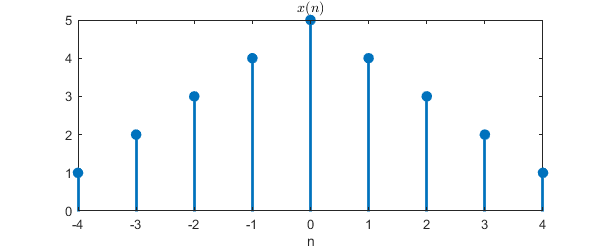

n = -4:4;
x3 =@(n)(5-abs(n)).*(n>=-4 & n<=4);
figure('Position',[500 400 600 250])
stem(n,x3(n),'filled','LineWidth',2)
title('$ x(n) $','Interpreter','latex')
xlabel('n')

b) Utilice Matlab para generar y graficar la señal $x_u(n)$ que se obtiene al incrementar la razon de muestreo con un factor I = 2.

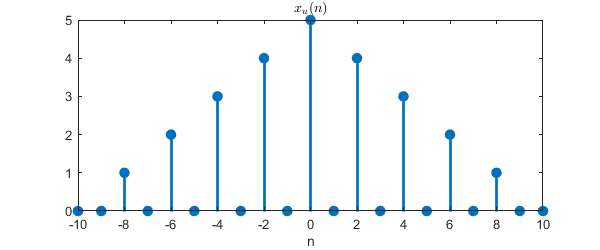

x3 =@(n)(5-abs(n)).*(n>=-4 & n<=4);
n = -10:10;
xu = upsample(x3(n),2);
figure('Position',[500 400 600 250])
n = -20:21;
stem(n,xu,'filled','LineWidth',2)
title('$ x_u(n) $','Interpreter','latex')
xlim([-10 10])
xlabel('n')

c) Utilice Matlab para generar y graficar la señal $x_d(n)$ que se obtiene al reducir la razón de muestreo con un factor D=2.

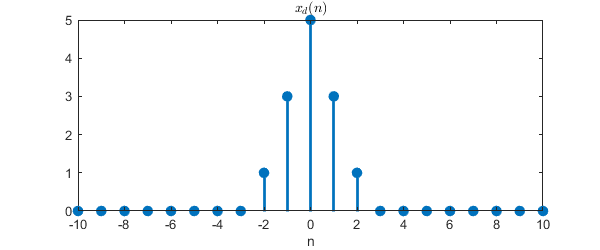

x3 =@(n)(5-abs(n)).*(n>=-4 & n<=4);
n = -20:20;
xu = downsample(x3(n),2);
figure('Position',[500 400 600 250])
n = -10:10;
stem(n,xu,'filled','LineWidth',2)
title('$ x_d(n) $','Interpreter','latex')
xlim([-10 10])
xlabel('n')

%Autor: Flores Chavarria Diego

clear all;

clc

close all;

impulso = @(n) n==0;

escalon = @(n) n>=0;

x1 = @(n) ( impulso(n) + escalon(n+4) - 2*escalon(n) + escalon(n-5) );

x2 = @(n) ( escalon(n+4)-escalon(n-5) );

y1 = @(n) ( (1/3)*( x2(n+1) + x2(n) + x2(n-1) ) );

y2 = @(n) ( ((4/5).^n).*x2(n) );

% Ejercicio 1

n = -10:10;

figure(1)

stem(n,x1(n),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

n = -10:10;

figure(2)

stem(n,x1(n-5),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

n = -10:10;

figure(3)

stem(n,x1(n+5),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

n = -10:10;

figure(4)

stem(n,x1(-n),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

n = -10:10;

figure(5)

stem(n,x1(-n+5),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

n = -10:10;

figure(6)

stem(n,x1(-n-5),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

%Ejercicio 2

n = -10:10;

figure(7)

stem(n,x2(n),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

n = -10:10;

figure(8)

stem(n,y1(n),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

n = -10:10;

figure(9)

stem(n,y2(n),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

%Ejercicio 3

n = -4:4;

x3 =@(n)(5-abs(n)).*(n>=-4 & n<=4);

figure(10)

stem(n,x3(n),'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

xu = upsample(x3(n),2);

figure(11)

n = -8:9;

stem(n,xu,'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')

xd = downsample(x3(n),2);

figure(12)

n = -4:4;

stem(n,xd,'filled','LineWidth',2)

title('x_1(n)')

xlabel('n')